# Introduction

This demo demonstrates how to change variables and component parameters in a ADS project, and how to run the simulation by means of `TADSInterface` class.

**Please read also *****Demo010L***** to be aware of this interface limitations, and required environmental variables which should be set in the Matalb session.**

# ADS Project

The project name is `VoltageSourceWithLoad_wrk` and it is located in the subfolder `ADSProjects` in this demo directory. 

The project is just an AC source with internal impedance `Rsrc` = 1 Ohm, which is loaded by a resistive load `Rload`. We will sweep the load resistance from 0.2 to 3 Ohm, read voltage and current, and plot dependence of power dissipated in the load versus the load resistance. As we can expect, the maximum power is reached when `Rsrc` = `Rload`.

# 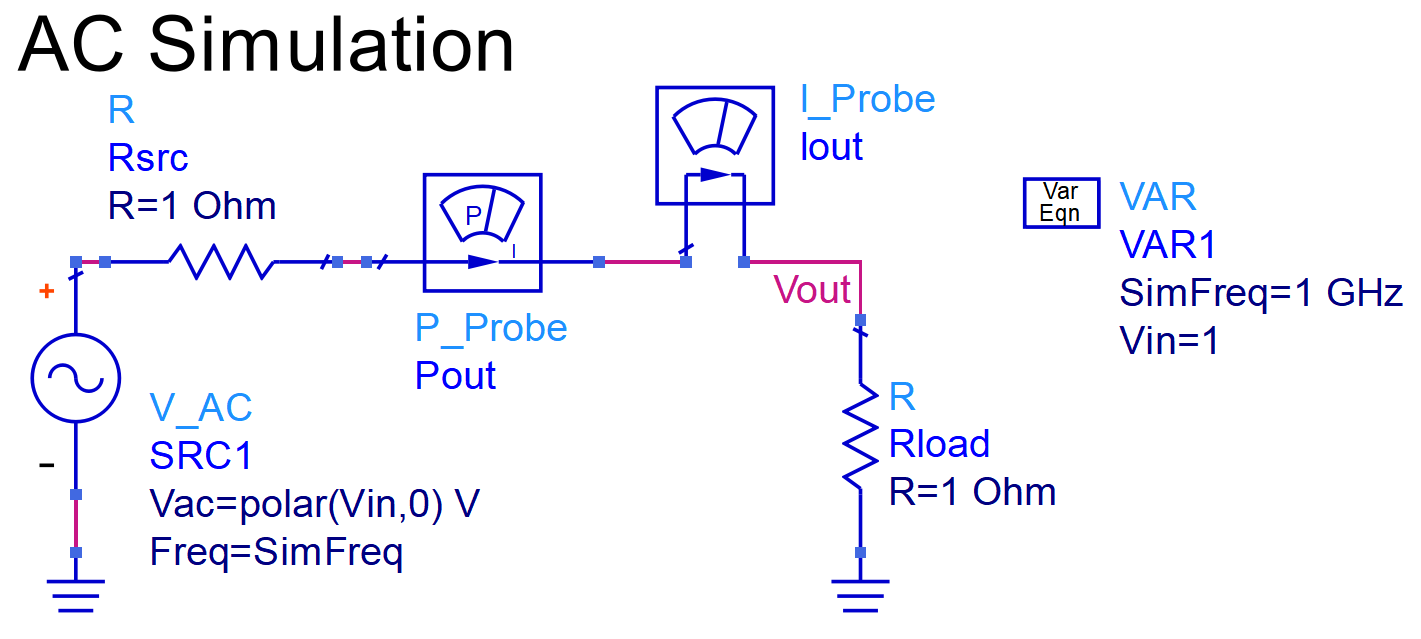

# Preparation

clc
clear
close all

% Create _TADSInterface_ object
ADS = TADSInterface();

% Anonymous function to convert S-parameters to dB
to_dB = @(s) 20*log10(abs(s));

Usually the ADS project must be open in ADS IDE in order to avoid potential problems with ADS libraries. However, this project doen't use external libraries, therefore it is not necessary to open the project.

# Specify Netlist and Dataset files

**NETLIST FILE**

The netlist file is generated by ADS when you run the simulation from there or press "*Simulate - Generate Netlist*" in the schematic window menu. **IMPORTANT! Don't forget to re-generate the netlist file if some modifications were done in the ADS IDE.**

The netlist file is normally located in the project directory and have name "*netlist.log*". 

ADS.NetlistFile = 'ADSProjects\VoltageSourceWithLoad_wrk\netlist.log';

**DATASET FILE**

The dataset file has name of the simulating cell, and has extension *.ds*. 

**IMPORTANT!** 

When the simulation is run from ADS IDE the dataset file is stored in *<Project_wrk>\****data****\<cell_name>.ds*. However, if the simulation is run from Matlab (or command line), the dataset file is stored in the project directory, i.e. *<Project_wrk>\<cell_name>.ds*.

ADS.DatasetFile = 'ADSProjects\VoltageSourceWithLoad_wrk\SingleFreq.ds'; 

NOTE that the dataset file is **NOT in the **`data`** sub-directory** since we will run simulation from Matlab in the following code!!!

# Do a parametric sweep

We will sweep the load resistance from 0.2 to 3 Ohm

Rload = 0.2:0.4:3;

The simulation frequency is specified as parameter (variable) `SimFreq` in the ADS project (see schematic).

We can change it using `ADS.ChangeParameter(ParamName, ParamValue, ParamType)` method. The 1st argument (`ParamName`) is a string with the parameter name, the 2nd argument (`ParamValue)` is the parameter value, and 3rd argument (*ParamType)* is the parameter type, which can be one of the following:

- **'double'**: in this case `ParamValue` must be a numeric value. For this specific exapmle (to change the frequency) we can call the method as `ADS.ChangeParameter('SimFreq', 3, 'double')`, which would replace the parameter value by 3** keeping units unchanged.**

- **'string'**: in this case `ParamValue` must be a string without double quotes, e.g. a file name `'C:\Path\File.ext'`. This `ParamValue` is used only for a string parameter values which are surrounded by double quotes in the netlist file, e.g. a touchstone file name for an SNP component. Since frequecny is not a string, this parameter type is not relevant for this example.

- **'custom'**: general case. In this case `ParamValue` must be a string, which will be written "as is" to the netlist as the parameter value. Please look inside the netlist file to see exact format and units the parameter has.

Here, we change the frequency to 3 GHz using "custom" parameter type. As was mentioned above, in this case the parameter value will be written to the netlist file "as is", therefore we need to specify the units as well.

ADS.ChangeParameter('SimFreq', '3 GHz', 'custom');

[17:18:53] A parameter with name "SimFreq" has been changed:
[17:18:53]   1) at the netlist line 31:
[17:18:53]     SimFreq=1 GHz
[17:18:53]     ↧↧↧ changed to ↧↧↧
[17:18:53]     SimFreq=3 GHz
[17:18:53] 


In the output above the changed parameter is highlighted with bold font, so you can control what has been changed and to what. A blue hyperlink is aslo provided, which when clicked opens the netlist file in the Matlab editor and highlights the line with the changed parameter.

One can also add an optional argument pair `'Test',true` to the method, which will print the information above without actual change of the netlist file, e.g. `ADS.ChangeParameter('SimFreq', '3 GHz', 'custom', 'Test',true)`*.*

The `ChangeParameter` method changes value of independent parameters in the project, e.g. defined in "*Var Eqn*" component. In order to change the parameter of an ADS component (like SNP, capacitor, etc.) one must use `ChangeComponentParameter` method instead, which is similar to the described above `ChangeParameter` method, but an additional argument (at the 1st place) is added which specifies the component name (e.g. "*R:Rload*" or "*S2P:SNP1*"):

`ADS.ChangeComponentParameter(ComponentName, ParamName, ParamValue, ParamType)`

The component name can be found in the netlist file, which can be be opened in Matlab editor by executing `ADS.OpenNetlist`.

Now, for each load value, we change the `Rload` value, run simulation and read voltage, current and power. See the code comments for more detatils.


NLoads = length(Rload);

% preallocate memory for the variables we will store 
Vout = nan(NLoads,1);  Iout = nan(NLoads,1);  Pout = nan(NLoads,1);

% Do Rload sweep
for ir=1:length(Rload)
    
    % Change the component (resistor) parameter. Since we are changing parameter of the component (resistor)
    % the method ChangeComponentParameter must be used.
    ADS.ChangeComponentParameter('R:Rload', 'R', Rload(ir), 'double');
    
    % Run ADS solver
    ADS.RunSimulation();
    
    % Read the simulated results from the dataset file and store them to our variables Vout, Iout and Pout. 
    % Please refer to the Demo010L for more details how to get result values from datasets.
    ADS.ReadDataset();
    Vout(ir) = ADS.GetVariableAsFunction('Vout', 'freq');
    Iout(ir) = ADS.GetVariableAsFunction('Iout.i', 'freq');
    Pout(ir) = ADS.GetVariableAsFunction('Pout.p', 'freq');
    
    % stop displaying output from next cycle
    ADS.MessageLevelOfDetails = 'none';  % can be 'none' or 'everything'
    
end

[17:18:53] Change parameter (at the netlist line 26):
[17:18:53]   R:Rload  Vout 0 R=3 Ohm Noise=yes
[17:18:53]   ↧↧↧ to ↧↧↧
[17:18:53]   R:Rload  Vout 0 R=0.2 Ohm Noise=yes
[17:18:53] 


[17:18:53] 
[17:18:53] *****************************************************************************
[17:18:53] ***                      ADS interface v1.2.001                           ***
[17:18:53] ***                Tested with ADS v2016.01, 2017, 2019                   ***
[17:18:53] ***             Chalmers University of Technology, Sweden                 ***
[17:18:53] ***      Oleg Iupikov, <a href="mailto:lichne@gmail.com">lichne@gmail.com</a>, <a href="mailto:oleg.iupikov@chalmers.se">oleg.iupikov@chalmers.se</a>         ***
[17:18:53] ***                      Last edit:  17-04-2019                           ***
[17:18:53] *****************************************************************************
[17:18:53] Running ADS simulator "hpeesofsim"...
[17:18:54] Done. Elapsed time is 01 sec
[17:18:54] 


[17:18:54] 1) Reading vectorset "AC1.AC"
[17:18:54]   Independent variables:
[17:18:54]     freq
[17:18:54]   Dependent variables:
[17:18:54]     Vout
[17:18:54]     SRC1.i
[17:18:54]     Iout.i
[17:18:54] 
[17:18:54] 2) Reading vectorset "aele_0.AC1"
[17:18:54]   Independent variables:
[17:18:54]     freq
[17:18:54]   Dependent variables:
[17:18:54]     Pout.p
[17:18:54] 


[17:18:54] Variable "Vout(freq)" is found in the vectorset 1 ("AC1.AC")


[17:18:54] Variable "Iout.i(freq)" is found in the vectorset 1 ("AC1.AC")


[17:18:54] Variable "Pout.p(freq)" is found in the vectorset 2 ("aele_0.AC1")


The output above first shows that parameter `R` of the component `R:Rload` was changed from 3 Ohm to 0.2 Ohm. The full line from the netlist file related to the component is displayed, and the changed part is highlighted with bold font.

Next the simulation was performed starting with the interface version banner. By default, only warnings and errors generated by the ADS solver are displayed in the Matlab command window, i.e. `ADS.RunSimulation()` is equivalent to `ADS.RunSimulation('Verbosity','warnings')`. Other options for the `'Verbosity'` argument are `'none'` (do not redirect anything from the ADS output to the Matlab command window), `'errors'` (show only solver errors), and `'all'` (redirect all ADS output). 

*NOTE! Since a parsing of the ADS messages is used to filter out warnings and errors, it may create problems if message format will be changed in future releases of ADS. In this case run simulation as *`RunSimulation('Verbosity','none')`* or *`RunSimulation('Verbosity','all')`*,  which do not use the message parsing.*

Then the dataset was read (starting with line "*1) Reading vectorset "AC1.AC"*"), displaying the independent and dependent variables stored in it. One can click the blue links to open the dataset dump (txt-file) at the line where corresponding variables are defined.

Finally, values of *Vout*, *Iout* and *Pout* were extracted from the read data.

# Plot sweep results

Here we plot  `Vout`, `Iout` and `Pout` as functions of `Rload` by using standard Matlab functions.

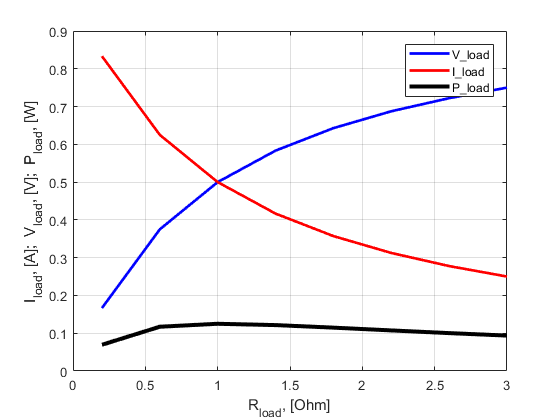

figure;
plot(Rload, Vout, '-b', 'LineWidth',2, 'DisplayName','V\_load');  hold on;
plot(Rload, Iout, '-r', 'LineWidth',2, 'DisplayName','I\_load');
plot(Rload, Pout, '-k', 'LineWidth',3, 'DisplayName','P\_load');
legend show; grid on; xlabel('R_{load}, [Ohm]'); ylabel('I_{load}, [A];  V_{load}, [V];  P_{load}, [W]');